# Example: Sampling from a Bi-modal Posterior

Author: Adolphus Lye (Email: adolphus.lye@liverpool.ac.uk)

## Problem: 

In this example, we wish to investigate the performance of the Ensemble sampler, proposed by [Goodman and Weare (2010)](https://projecteuclid.org/download/pdf_1/euclid.camcos/1513731992), in sampling from a more complex target distribution with two peaks. 

Consider the following Bayesian Inference problem:

Let's suppose we have a $2 \times 2$ square matrix, $M$, taking on the following form:


$$\textit{M} = \pmatrix{\alpha_1+\alpha_2 & -\alpha_2 \cr -\alpha_2 & \alpha_2}$$


whereby $\alpha_1$ and $\alpha_2$ are the matrix elements. Examples of matrices taking on such form include the Stiffness matrix in the [Tuned Mass Damping system](https://link.springer.com/article/10.1007/s40091-016-0136-7). The matrix elements take on fixed real values but are unknown to the analyst, and hence, $\alpha_1$ and $\alpha_2$ are to be estimated. Lets take the true values to be: $\left\lbrace \alpha_1 ,\alpha_2 \right\rbrace =\left\lbrace 0\ldotp 5,1\ldotp 5\right\rbrace$.

The matrix $M$ yields $2$ real solutions of eigenvaues, $\lambda^{\mathit{model}}$, each taking on the following respective mathematical expressions:


$$\lambda_{1}^{model} = \frac{(\alpha_1+2\alpha_2)+\sqrt{{\alpha_1}^2+4{\alpha_2}^2}}{2}$$



$$\lambda_{2}^{model} = \frac{(\alpha_1+2\alpha_2)-\sqrt{{\alpha_1}^2+4{\alpha_2}^2}}{2}$$


Putting everything in a physcial context, the square matrix $\textit{M}$ represents a hypothetical physical system and its Eigenvalues $\lambda$ represent the possible measurements/observations that can be made from that system. However, in reality, measurements can never be measured "perfectly" and would inevitably be corrupted with measurement "noise". As such, the "noisy" eigenvalues, $\lambda_{i}^{noisy}$, are represented as such: 

 
$$\lambda_{1}^{noisy} = \frac{(\alpha_1+2\alpha_2)+\sqrt{{\alpha_1}^2+4{\alpha_2}^2}}{2} + \epsilon_1$$



$$\lambda_{2}^{noisy} = \frac{(\alpha_1+2\alpha_2)-\sqrt{{\alpha_1}^2+4{\alpha_2}^2}}{2} + \epsilon_2$$


whereby $\epsilon_{i}$ (for $i = 1,2$) is the "noise" term. $\epsilon_{i}$ is assumed to be a zero-mean Gaussian random variable with standard deviations: $\left\lbrace \sigma_1 ,\sigma_2 \right\rbrace =\left\lbrace 1\ldotp 0,0\ldotp 1\right\rbrace$. We assume a set of 15 of such measurements are available for us to infer $\alpha_1$ and $\alpha_2$.

This problem is set as an inverse problem whereby the parameters of interest (in this case, $\alpha_1$ and $\alpha_2$) are calculated based on the observations (in this case, $\lambda_{1}^{noisy}$ and $\lambda_{2}^{noisy}$) made from the system of interest. In other words, the matrix elements, $\alpha_1$ and $\alpha_2$, are being calculated from the "noisy" measurements contrary to the forward problem.

In a Bayesian Model Updating problem, the posterior (i.e. the target distribution) is defined as follows:


$$P(\mathbf{\theta}|D) = \frac{P(D|\mathbf{\theta})\cdot P(\mathbf{\theta})}{P(D)}$$


whereby $\mathbf{\theta}$ is a vector of the parameter(s) to be estimated, $D$ is defined to be the measurements or observations made form the system, $P(\mathbf{\theta})$is defined as the Prior distribution, $P(D|\mathbf{\theta})$ is defined as the Likelihood function, $P(\mathbf{\theta}|D)$ is defined as the posterior distribution, and $P(D)$ is defined as the Evidence and is also the normalisation constant of the posterior distribution. 

In the context of this problem, $\mathbf{\theta}$ would be the matrix elements, $\theta_1$ and $\theta_2$, we wish to estimate. $D$ are the set of measurements or observations which in this case would be the "noisy" Eigenvalues: $\lambda_{1}^{noise}$ and $\lambda_{2}^{noise}$. However, given that $P(D)$is a numerical constant, it is usually neglected and we represent the posterior implicitly as follows:

    
$$P(\mathbf{\theta}|D) \propto P(D|\mathbf{\theta}) \cdot P(\mathbf{\theta})$$


An illustration of the posterior is provided below:

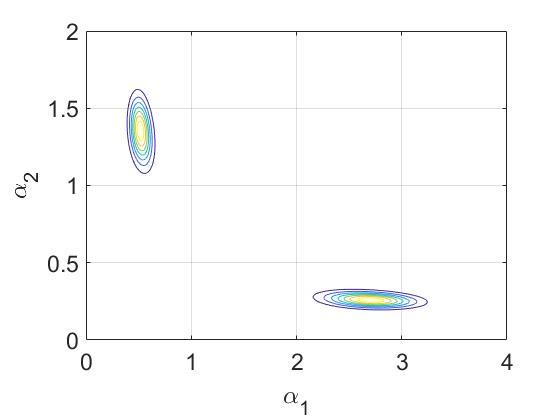

To demonstrate the robustness of the Ensemble sampler in sampling from such distribution, its sampling performance will be compared against that of the [Transitional Markov Chain Monte Carlo (TMCMC)](https://doi.org/10.1061/(ASCE)0733-9399(2007)133:7(816)) sampler. For this example, sampling will be done by the Ensemble sampler using 10 chains, each chain generating 500 samples, whereas for the TMCMC sampler, 5000 samples will be obtained directly from the posterior.

## 1) Setting-up the problem:

### a) Defining the parameters:

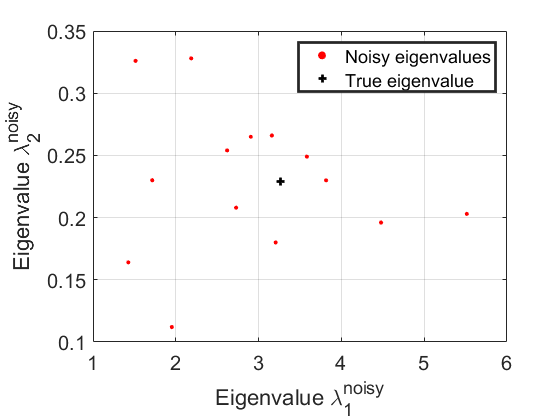

% True values of alphas:
dim = 2; % number of parameters to be estimated
alpha_1 = 0.5;
alpha_2 = 1.5;
alpha = [alpha_1,alpha_2];

% Number of measurements:
Nobservations = 15;  

% Eigenvalues/Measurements (15 measurements):
eigenvalue_1 = [1.514;4.010;3.160;3.206;2.186;1.715;2.728;5.515;1.952;...
                4.479;1.427;2.906;3.815;3.583;2.620];
eigenvalue_2 = [0.326;0.302;0.266;0.180;0.328;0.230;0.208;0.203;0.112;...
                0.196;0.164;0.265;0.230;0.249;0.254];
eigenvalue = [eigenvalue_1, eigenvalue_2];

% To plot the 2D scatter plot of the model:
figure();
hold on; box on; grid on;
h1 = scatter(eigenvalue_1, eigenvalue_2, 10, 'r', 'filled');
plot(3.2702, 0.2293, 'k +','LineWidth', 2);
xlabel('Eigenvalue \lambda^{noisy}_1', 'Fontsize', 20)
ylabel('Eigenvalue \lambda^{noisy}_2', 'Fontsize', 20)
legend('Noisy eigenvalues', 'True eigenvalue','LineWidth',2)
set(gca,'fontsize', 15)

### b) Define the Model to calculate eigenvalues of Matrix *M*:

modelOutput_1 = @(x) 0.5*((x(:,1) + 2*x(:,2)) + (x(:,1).^2 + 4*(x(:,2).^2)).^0.5);
modelOutput_2 = @(x) 0.5*((x(:,1) + 2*x(:,2)) - (x(:,1).^2 + 4*(x(:,2).^2)).^0.5);

### c) Setting up the posterior distribution:

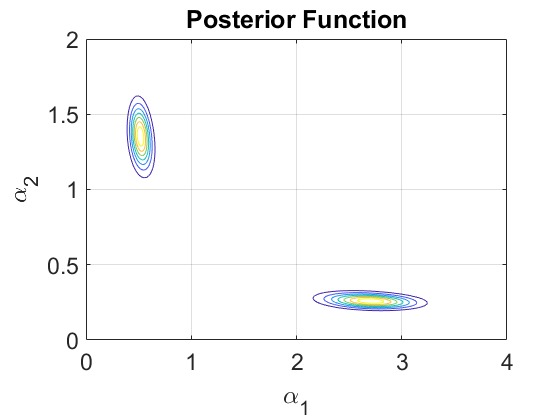

%% The prior in this problem takes the form of a non-informative uniform prior.
% Define the Prior:
lowerBound = 0.01; upperBound = 4; 
prior_pdf = @(x) unifpdf(x(:,1),lowerBound,upperBound).*unifpdf(x(:,2),lowerBound,upperBound);
prior_rnd = @(N) [unifrnd(lowerBound,upperBound,N,1),unifrnd(lowerBound,upperBound,N,1)];

%% The likelihood function here follows a Gaussian distribution.
% Define the Log-Likelihood function:
like_std_1 = 1; like_std_2 = 0.1;
logl_1 = @(x) - 0.5 * (1/like_std_1)^2 *(eigenvalue_1 - modelOutput_1(x))' * (eigenvalue_1 - modelOutput_1(x));
logl_2 = @(x) - 0.5 * (1/like_std_2)^2 *(eigenvalue_2 - modelOutput_2(x))' * (eigenvalue_2 - modelOutput_2(x));
logl = @(x) (logl_1(x) + logl_2(x));

% Define the log posterior:
log_posterior = @(x) log(prior_pdf(x)) + logl(x);

% To generate an illustrative contour plot of the bi-modal posterior:
[X1,X2] = meshgrid(0:0.01:4, 0:0.01:4);
in1 = X1(:); in2 = X2(:);
Z = zeros(length(in1),1);
for i = 1:length(in1)
        Z(i) = log_posterior([in1(i) in2(i)]);
end
Z = reshape(Z, size(X1));

figure();
hold on; box on; grid on;
contour(X1,X2,exp(Z))
colormap(parula)
title('Posterior Function')
xlim([0 4])
ylim([0 2])
xlabel('\alpha_1')
ylabel('\alpha_2')
set(gca, 'fontsize', 17)

## 2) Sample using the Ensemble sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the ensemble:
Nwalkers = 5*dim;  

% Defining the starting point of each chain:
start_emcmc = prior_rnd(Nwalkers);

% Defining the sample size per chain:
Nsamples_emcmc = 500;

% Defining the burn-in length of each chain:
BurnIn_emcmc = 50;

% Defining the step-size of each chain:
step_size = 3; 
% Note: The step-size is chosen such that it gives the Ensemble sampler an
% overall acceptance rate that is close to 0.235.

### b) Initiate the Ensemble sampler:

tic;
EMCMC = EMCMCsampler(start_emcmc,log_posterior,Nsamples_emcmc,'StepSize',step_size,'burnin',BurnIn_emcmc);

timeEMCMC = toc;
fprintf('Time elapsed is for the Ensemble sampler is: %f \n',timeEMCMC)

Time elapsed is for the Ensemble sampler is: 9.068216 


fprintf('The acceptance level of the Ensemble sampler is: %d. \n',EMCMC.acceptance)

The acceptance level of the Ensemble sampler is: 2.247955e-01. 


### c) To obtain the sample output:

% To extract the samples:
samps_emcmc = EMCMC.samples;

% Note that the output is in the form of a Nsamples x dim x Nwalker matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_emcmc = permute(samps_emcmc, [2 1 3]);
samples_emcmc = samples_emcmc(:,:)';

## 3) Sample using the TMCMC sampler:

### a) Defining the input parameters:

% Defining the total number of samples to obtain:
Nsamples_tmcmc = 5000;

### b) Initiate the TMCMC sampler:

tic;
TMCMC = TMCMCsampler('nsamples',Nsamples_tmcmc,'loglikelihood',logl,...
               'priorpdf',prior_pdf,'priorrnd',prior_rnd,'burnin',0);

TMCMC: Iteration j =  1, pj1 = 0.009338
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  2, pj1 = 0.072262
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  3, pj1 = 0.260936
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  4, pj1 = 0.833591
Computing the weights ...
Markov chains ...


TMCMC: Iteration j =  5, pj1 = 1.000000
Computing the weights ...
Markov chains ...




timeTMCMC = toc;
fprintf('Time elapsed is for the TMCMC sampler: %f \n',timeTMCMC)

Time elapsed is for the TMCMC sampler: 83.877806 


### c) To obtain the sample output:

% To extract the samples:
samples_tmcmc = TMCMC.samples;

## 4) Analysing the Results:

### a) Generating the scatterplot profiles:

#### i) Ensemble sampler: Scatterplot profile for posterior

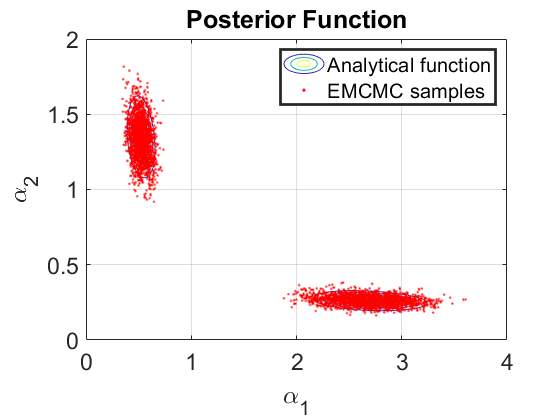

figure();
hold on; box on; grid on
contour(X1,X2,exp(Z))
colormap(parula)
title('Posterior Function')
xlim([0 4])
ylim([0 2])
scatter(samples_emcmc(:,1),samples_emcmc(:,2), 15, 'r.')
xlabel('\alpha_1')
ylabel('\alpha_2')
legend('Analytical function','EMCMC samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

#### ii) TMCMC sampler: Scatterplot profile for posterior

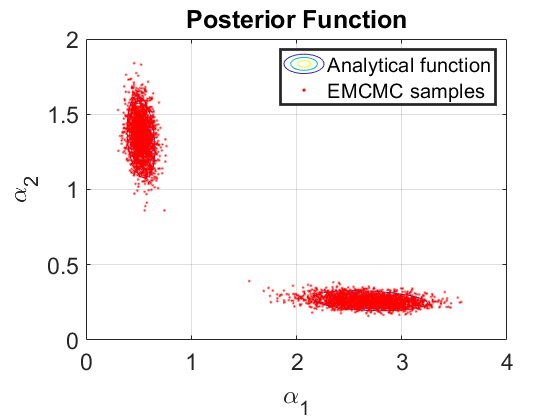

figure();
hold on; box on; grid on
contour(X1,X2,exp(Z))
colormap(parula)
title('Posterior Function')
xlim([0 4])
ylim([0 2])
scatter(samples_tmcmc(:,1),samples_tmcmc(:,2), 15, 'r.')
xlabel('\alpha_1')
ylabel('\alpha_2')
legend('Analytical function','EMCMC samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

### b) Generating the Scatterplot Matrix:

#### i) Ensemble sampler: Scatterplot matrix

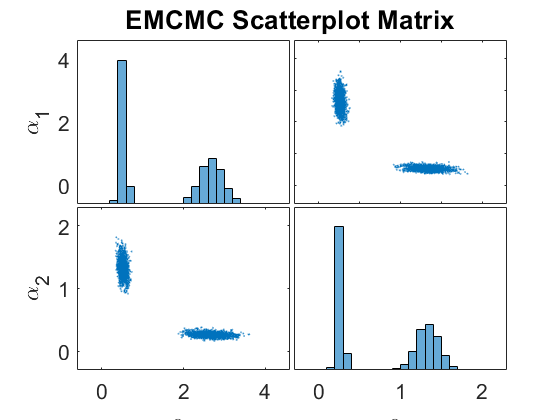

figure();
[~,ax1] = plotmatrix(samples_emcmc);
title('EMCMC Scatterplot Matrix', 'Fontsize', 20);
for i=1:2
    ax1(i,1).FontSize = 16; 
    ax1(2,i).FontSize = 16; 
    ylabel(ax1(i,1),sprintf('\\alpha_{%d}', i));
    xlabel(ax1(2,i),sprintf('\\alpha_{%d}', i));
end
set(gca,'FontSize',18)

#### ii) TMCMC sampler: Scatterplot matrix

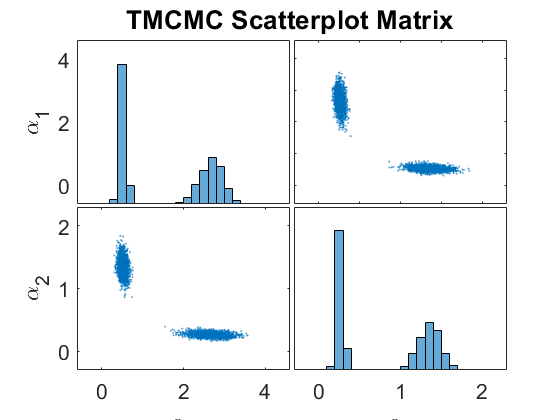

figure();
[~,ax2] = plotmatrix(samples_tmcmc);
title('TMCMC Scatterplot Matrix', 'Fontsize', 20);
for i=1:2
    ax2(i,1).FontSize = 16; 
    ax2(2,i).FontSize = 16; 
    ylabel(ax2(i,1),sprintf('\\alpha_{%d}', i));
    xlabel(ax2(2,i),sprintf('\\alpha_{%d}', i));
end
set(gca,'FontSize',18)

### c) Generating the Empirical CDFs:

#### i) Plot the Analytical Marginal CDFs for $\alpha_1$and $\alpha_2$:

% Re-defining the model output:
Output_1 = @(x,y) 0.5*((x + 2*y) + (x.^2 + 4*(y.^2)).^0.5);
Output_2 = @(x,y) 0.5*((x + 2*y) - (x.^2 + 4*(y.^2)).^0.5);

% Re-defining the log-likelihood function:
loglike_1 = @(x,y) - 0.5 * (1/like_std_1)^2 *(eigenvalue_1 - Output_1(x,y)) .* (eigenvalue_1 - Output_1(x,y));
loglike_2 = @(x,y) - 0.5 * (1/like_std_2)^2 *(eigenvalue_2 - Output_2(x,y)) .* (eigenvalue_2 - Output_2(x,y));
loglike = @(x,y) sum((loglike_1(x,y) + loglike_2(x,y)));

% Re-defining the log-prior function:
prior = @(x,y) unifpdf(x,lowerBound,upperBound).*unifpdf(y,lowerBound,upperBound);
log_priorpdf = @(x,y) log(prior(x,y));
logpdf = @(x,y) log_priorpdf(x,y) + loglike(x,y);

% Defining the posterior in real space:
fun = @(x,y) exp(logpdf(x,y));

% Marginal distribution of alpha_1:
fun_x1 = @(x) integral(@(y) fun(x,y),lowerBound,upperBound);
% Marginal distribution of alpha_2:
fun_x2 = @(y) integral(@(x) fun(x,y),lowerBound,upperBound);

% To generate marginal CDFs for alpha_1 and alpha_2
fun_x1_out = zeros(1000,1); fun_x2_out = zeros(1000,1);
x1 = linspace(lowerBound,upperBound,1000); x2 = linspace(lowerBound,upperBound,1000);
for i = 1:1000
fun_x1_out(i) = fun_x1(x1(i)); 
fun_x2_out(i) = fun_x2(x2(i));
end

% Analytical marginal CDF for x1 (after normalization):
fun_x1_out = normalize(cumsum(fun_x1_out),'range',[0,1]);

% Analytical marginal CDF for x2 (after normalization):
fun_x2_out = normalize(cumsum(fun_x2_out),'range',[0,1]);

#### ii) Plot the ECDFs for $\alpha_1$and $\alpha_2$:

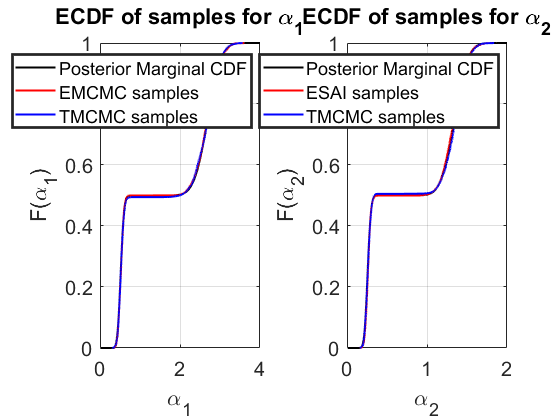

figure();
subplot(1,2,1)
hold on; box on; grid on;
plot(x1',fun_x1_out,'k','LineWidth',1.5)
[f1a,x1a] = ecdf(samples_emcmc(:,1));
plot(x1a,f1a,'r','LineWidth',1.5)
[f1b,x1b] = ecdf(samples_tmcmc(:,1));
plot(x1b,f1b,'b','LineWidth',1.5)
xlabel('\alpha_1')
ylabel('F(\alpha_1)')
legend('Posterior Marginal CDF', 'EMCMC samples', 'TMCMC samples', 'linewidth',2);
title('ECDF of samples for \alpha_1')
set(gca, 'Fontsize', 15)

subplot(1,2,2)
hold on; box on; grid on;
plot(x2',fun_x2_out,'k','LineWidth',1.5)
[f2a,x2a] = ecdf(samples_emcmc(:,2));
plot(x2a,f2a,'r','LineWidth',1.5) 
[f2b,x2b] = ecdf(samples_tmcmc(:,2));
plot(x2b,f2b,'b','LineWidth',1.5) 
xlabel('\alpha_2')
ylabel('F(\alpha_2)')
xlim([0 2])
legend('Posterior Marginal CDF', 'ESAI samples', 'TMCMC samples', 'linewidth',2);
title('ECDF of samples for \alpha_2')
set(gca, 'Fontsize', 15)

### d) Plotting scatterplot results of the Model updating:

#### i) Ensemble sampler: Model updating results

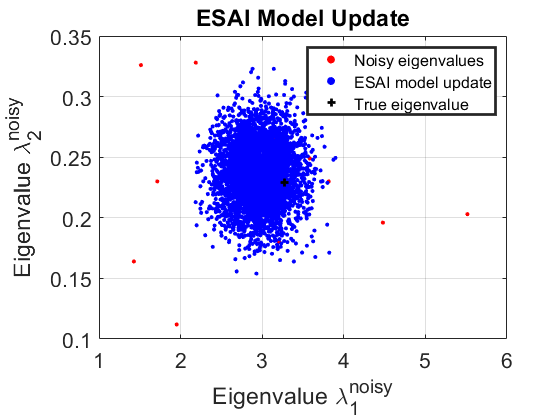

figure;
hold on; box on; grid on;
scatter(eigenvalue_1, eigenvalue_2, 10, 'r', 'filled');
emcmc_update = [modelOutput_1(samples_emcmc), modelOutput_2(samples_emcmc)];
scatter(emcmc_update(:,1), emcmc_update(:,2), 10, 'b', 'filled');
title('ESAI Model Update')
legend('Noisy eigenvalues', 'ESAI model update','Fontsize',12, 'LineWidth',2)
plot(3.2702, 0.2293, 'k +',"LineWidth", 2,'DisplayName','True eigenvalue');
xlabel('Eigenvalue \lambda^{noisy}_1','FontSize',20)
ylabel('Eigenvalue \lambda^{noisy}_2','FontSize',20)
set(gca,'FontSize',16)

#### ii) TMCMC sampler: Model updating results

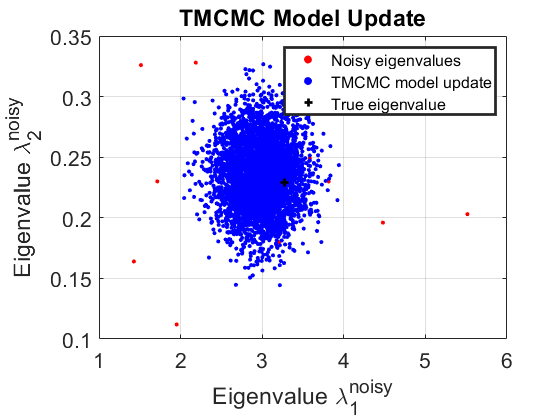

figure();
hold on; box on; grid on;
scatter(eigenvalue_1, eigenvalue_2, 10, 'r', 'filled');
tmcmc_update = [modelOutput_1(samples_tmcmc), modelOutput_2(samples_tmcmc)];
scatter(tmcmc_update(:,1), tmcmc_update(:,2), 10, 'b', 'filled');
title('TMCMC Model Update')
legend('Noisy eigenvalues', 'TMCMC model update','Fontsize',12, 'LineWidth',2)
plot(3.2702, 0.2293, 'k +',"LineWidth", 2,'DisplayName','True eigenvalue');
xlabel('Eigenvalue \lambda^{noisy}_1','FontSize',20)
ylabel('Eigenvalue \lambda^{noisy}_2','FontSize',20)
set(gca,'FontSize',16)

## 5) Save the data:

% To save all the data from this file:
save Example_Bimodal_Posterior.mat;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%